# Lab 01 - Introduction to Matlab

## 1. Objective

Introducing students to the Matlab development environment.

## 2. Theoretical aspects

The following aspects shall be explained

### 2.1 Matlab Window

Main windows:

- Command line

- Editor

- Workspace

One can write commands directly at Command Line, or write a script file and run it. For one-liners, write them in command line. For longer programs, use a separate script (using a script is the recommended way).

### 2.2. Scalar-based operations

Define scalar variables:

a = 5

a = 5

b = 8.4

b = 8.4000

Ending command with a semicolon (;) suppresses the output in the command window. Operation is still executed. Using ; is recommended practice.

a = 7

a = 7

b = 5;

Do arithmetic operations with scalars (+ - * / ^):

c = a/b

c = 1.4000

d = a^2 + 7*b - 3;

Logical operations (comparisons etc):

a > b

ans = logical
   1


l = (c <= d)

l = logical
   1


Trigonometric functions and predefined constants (`pi`):

x = cos(2.5*pi)

x = 3.0616e-16

Other functions (exponential, logarithm, square root etc.):

y = exp(x) + log10(7.5/a) + sqrt(44)

y = 7.6632

### 2.3 Array-based operations (vectors / matrices)

Define arrays with [ ... ]:

V = [1, 2, 3, 4, 5]                % V is a vector (values arranged in a row)

V =      1     2     3     4     5


A = [1, 2, 3;  4, 5, 6; 7, 8, 9]   % A is a matrix. Each row ends with ;

A =      1     2     3
     4     5     6
     7     8     9


Create matrices full of 0 or 1 with functions `zeros()` and `ones()`:

A = zeros(3,5);        % Make a matrix of size 3x5 full of zeros
B = ones(1, 1000);     % Make a vector of 1000 elements all equal to 1
C = 7*ones(1, 20000);  % Make a vector of 20000 elements equal to 7

Defining vectors via start:step:stop or `linspace()`:

D = 7:0.01:10;              % Make a vector going from 7 to 10 with steps of 0.1
E = linspace(10, 100, 50);  % Make a vector going from 10 to 100 in 50 equal steps

Array indexing, access to elements, modifying some values

Note: indexing starts at 1, not 0 like in C/Java/Python etc. First element of a vector is V(1)

A(2,3) = 55;
V(2) = 4;
i = 3;   V(i) = 56.789;  
V2 = V(3:5)                 % Take from V only from 3rd element to 5th element

V2 =    56.7890    4.0000    5.0000


V3 = V(3:end)               % Take from V only from 3rd element to the end

V3 =    56.7890    4.0000    5.0000


Select rows or columns from a matrix:

A = [1,2,3;   4,5,6;   7,8,9];  % Let's make a matrix
Apartial = A(1,:)           % Take from A row 1 and columns all. Result is a row vector.

Apartial =      1     2     3


Ap2      = A(:,2)           % Take from A rows all and column 2. Result is a column vector.

Ap2 =      2
     5
     8


Asmall   = A(1:2, 1:2)      % Take from A rows 1 to 2, columns 1:2. Result is a 2x2 submatrix from upper-left corner of A.

Asmall =      1     2
     4     5


Arithmetic operations with arrays:

A = [1, 2, 3];
B = [3, 3, 4];
C = [1, 1, 1; 2, 2, 2; 3, 3, 3]

C =      1     1     1
     2     2     2
     3     3     3



D = A+B;    % sum of two vectors = a vector
E = A*C;    % 1x3 vector multiplied with 3x3 matrix
F = C*B'    % ' means "transposed". Multiply a 3x3 matrix with a 3x1 column vector

F =     10
    20
    30


CC  = C*C;
CC2 = C^2;     % A^2 = A*A = matrix multiplication A with A

Broascasting:

V = A + 3;   % A is a vector, 3 is expanded to correct size, result is also a vector

Element-wise operations (.^):

Z = A.^2   % .^ means square operation is applied to each individual element

Z =      1     4     9


Y = C.^2   % .^2 means every element is raised to power 2. The shape of Y is the same as of C.

Y =      1     1     1
     4     4     4
     9     9     9


Logical operations (comparisons etc) with arrays

a = (A > 2);   % Each element is compared

Functions applied to arrays (trigonometric, mathematical functions, length/min/max/sum, etc)

A = 0:0.1:(4*pi);   % A vector going from 0 to 4pi
X = sin(A);         % X is a vector. sin() is applied to every element of A
Y = sqrt(A);
S = sum(A);         % sum of vector
minval = min(A)

minval = 0

maxval = max(A)

maxval = 12.5000

len  = size(A)      % Return size of A, i.e. [1, 126]     (1 row, 126 columns)

len =      1   126


len1 = size(A,2)    % Return size of A along second dimension (126)

len1 = 126

Concatenation of arrays

A = [1,2,3];
B = [4,5,6];
C = [A, B]          % A is joined on the right side with B => C is [1,2,3,4,5,6]

C =      1     2     3     4     5     6


D = [A; B]          % A is joined on the lower side with B => D is a matrix with two rows

D =      1     2     3
     4     5     6


E = [A, zeros(1,10)]  % E is A with 10 values of 0 appended at the end

E =      1     2     3     0     0     0     0     0     0     0     0     0     0


Graphical representation of a vectors with `plot()` and `stem()`:

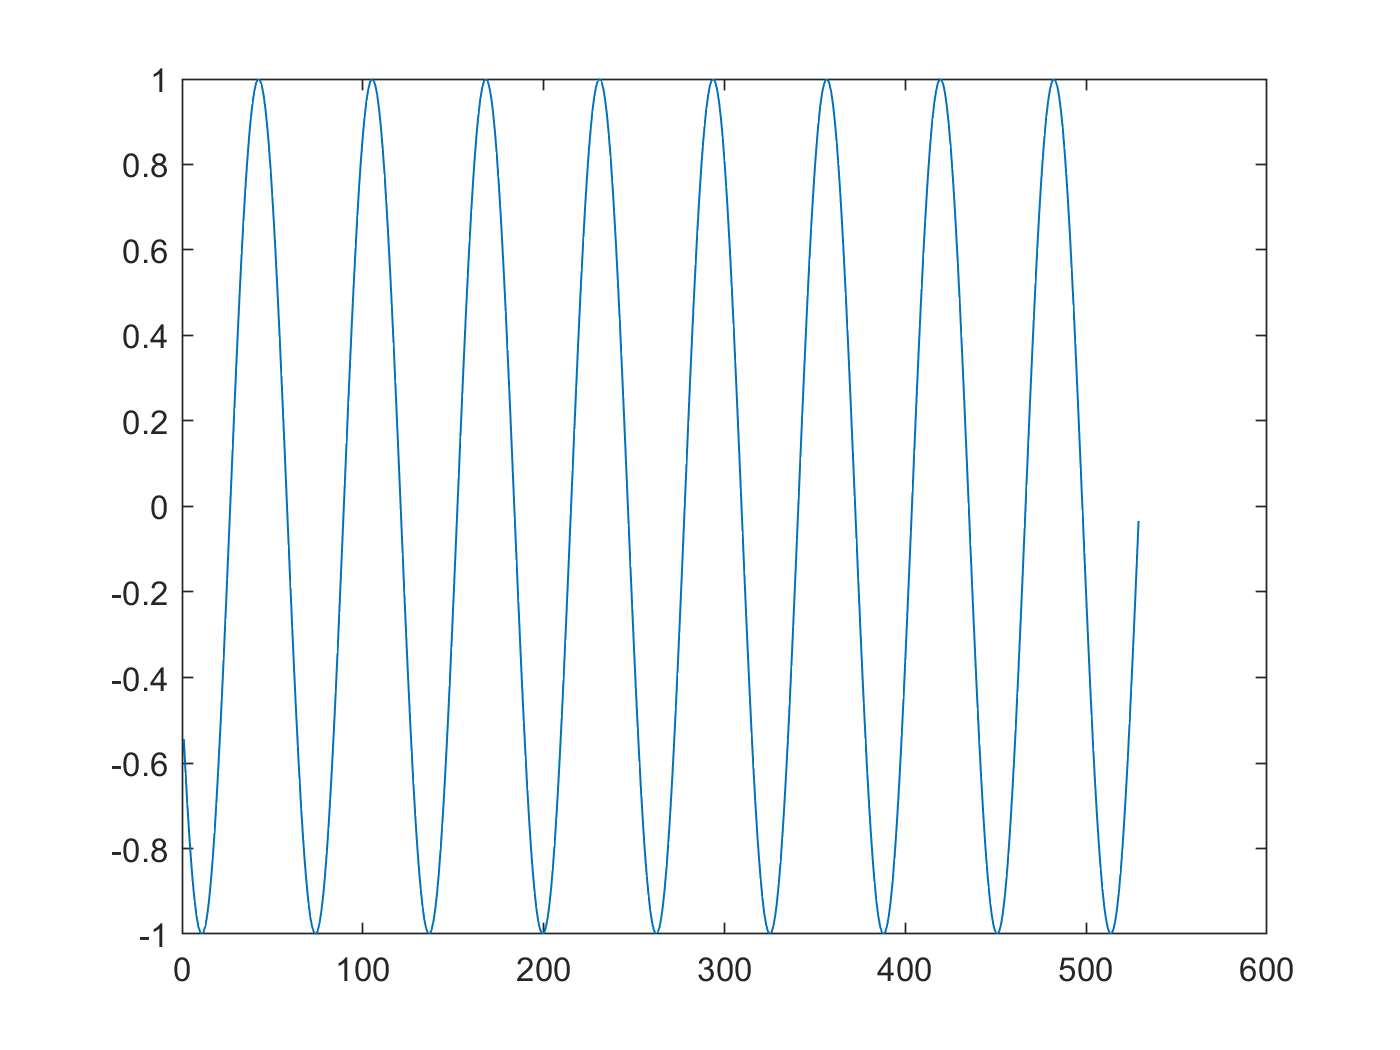

A = 10:0.1:(20*pi);   % A vector going from 0 to 4pi
X = sin(A);           % X is a vector. sin() is applied to every element of A
plot(X)       % Use plot() to display values like a continous function

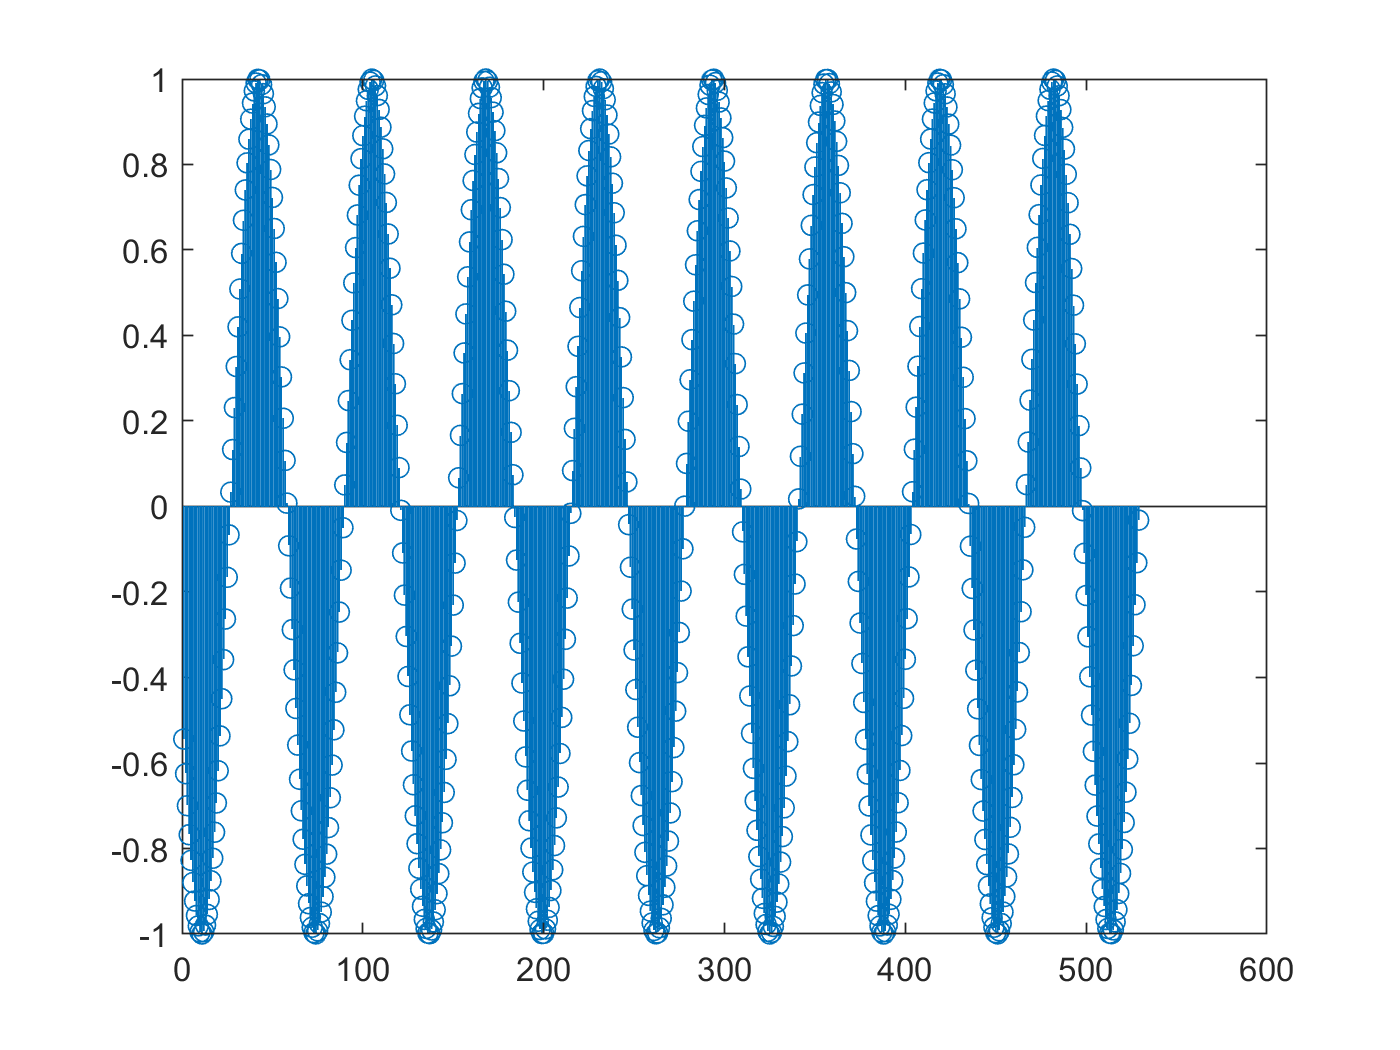

stem(X)       % Use stem() to display values with vertical sticks, like a discrete signal

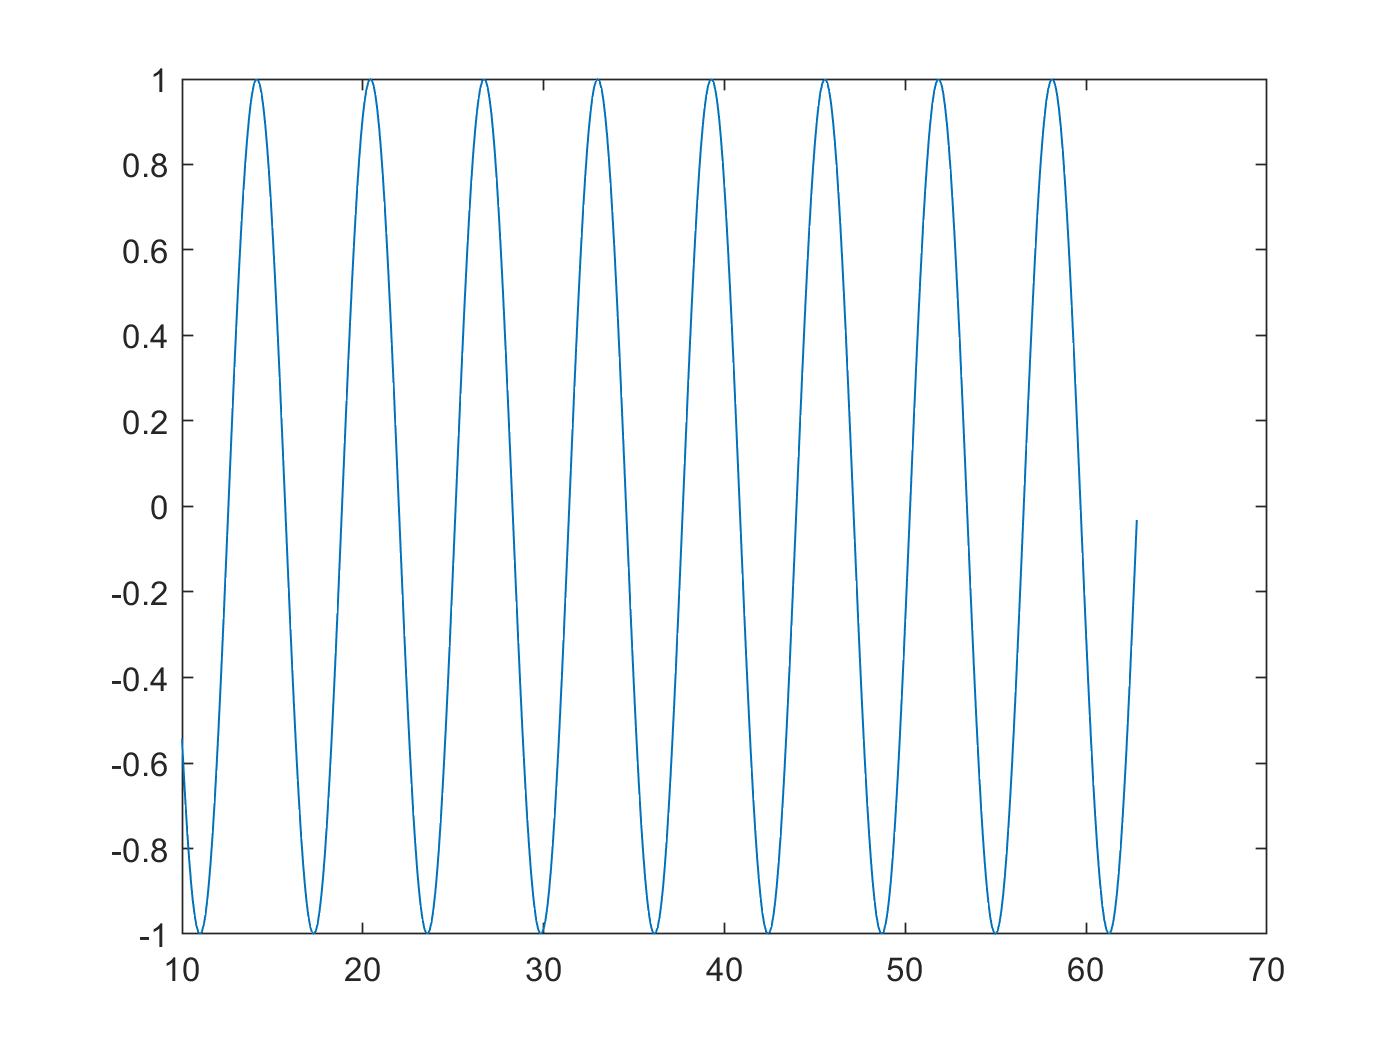

plot(A, X)    % Like plot(X), but puts values in A on the Ox axis

### 2.4 Keywords

If-then

a = sqrt(123)

a = 11.0905

if (a >= 10)
    b = 15;
end

a = sqrt(123)

a = 11.0905

if (a >= 10)
    b = 15;
else
    c = 'ala bala portocala';   % c is a string
end

While:

a = 5;
i = 0

i = 0

while (a < 20)
    a = a + 0.2;
    i = i + 1;
end
fprintf('It took %d loops for a to exceed 20', i);

It took 76 loops for a to exceed 20

## 3. Exercises

1. Define two variables $a=5$ and $b=0.3
$ and compute $a+b$, $\frac{a}{b}
$, $a^b$, $e^{a + ln(b)}$, $sin(a) + cos (b + \frac{\pi}{2})$

2. Define a vector A with 10 zeros, a matrix B of size $4 \times 6$ with all elements equal to 1, and a vector C with odd numbers from 1 la 21 (both included).

- Change the third element of A to 5

- Change element B(2,4) to 7

- Square all the elements of C, and save the result as a new vector D.

- Compute E = 4C - 50.

- Compare element-wise the vectors C and E. How many elements of C are larger than the corresponding elements from E? (use functions to calculate this, don't just count it yourselves)

- Apply sin() to all the elements of D

3. Define a vector $t$ with 1000 elements uniformly spaced between 0 and 10. Compute and plot $\cos(2 \pi f t)$, where f = 0.5.

4. Plot the signal $\sin(2 \pi f t + \frac{\pi}{4})$, with f = 0.2, for a duration of 3 periods.

## 4. Final questions

1. TBD